Write the loop closer equations here.

/*

*/

% small 'a' represents angular acceleration
% 'A' represents accleration 
a2=2; %rad/s^2
O2A=L(1);
AC=L(2);
AB=L(3);
CB=L(4);
CD=L(5);
DO6=L(6);
O2B=L(7);
O2O6=L(8);

a3 ($\dot\theta_3
$) is the angular accleration of link 3.Which is also equal to $\dot\theta_4
$ (see diagram in angles.mlx)

a3=(  AB.*(sin(T(2,:)+tB).*(w3.^2))+O2A.*(cos(T(1,:)).*a2) ...
    -O2A.*(sin(T(1,:)).*(w2.^2))  )./...
    ( AB.*(cos(T(2,:)+tB)) );


A4=-O2A.*(cos(T(1,:)).*(w2.^2))-O2A.*(sin(T(1,:)).*a2)+...
    AB.*(cos(T(2,:)+tB).*(w3.^2))+AB.*(sin(T(2,:)+tB).*a3);


[a5,a6]=solve_for_a5_a6(L,T,w2,w3,w4,w5,w6,a2,a3);

Ploting the variables

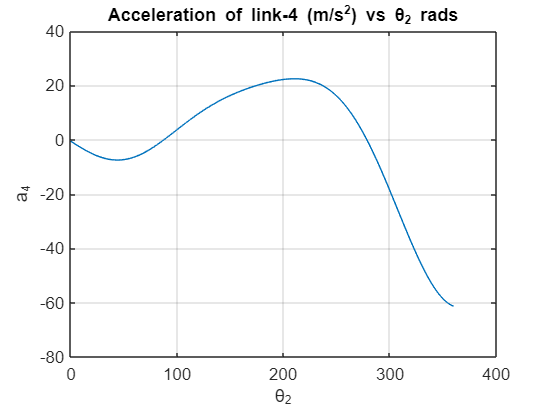

%****plots******
figure
plot(T(1,:)*180/pi,A4)
xlabel('\theta_2')
ylabel('a_4')
title('Acceleration of link-4 (m/s^2) vs \theta_2 rads')
grid on

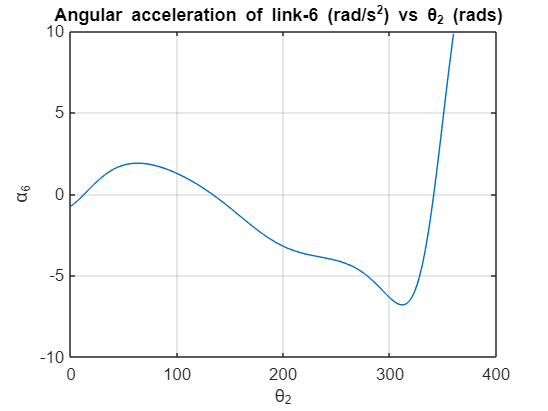


figure
plot(T(1,:)*180/pi,a6)
xlabel('\theta_2')
ylabel('\alpha_6')
title('Angular acceleration of link-6 (rad/s^2) vs \theta_2 (rads) ')
grid on


clearvars O2A AC AB CB CD DO6 O2B O2O6